# Spazi di colore

In questa demo mostreremo alcune caratteristiche degli spazi di colore RGB (formato di acquisizione e di display di immagini e video) e YCbCr (formato preferenziale per la compressione). Vedremo anche come passare dall'uno all'altro spazio e come sfruttare la diversa sensibilità dell'occhio umano alla crominanza per introdurre una prima tecnica di compressione percettuale delle immagini. 

### Lettura dell'immagine

Leggiamo un'immagine in formato non compresso, RGB. Tipico esempio di tale formato sono i file `.bmp`

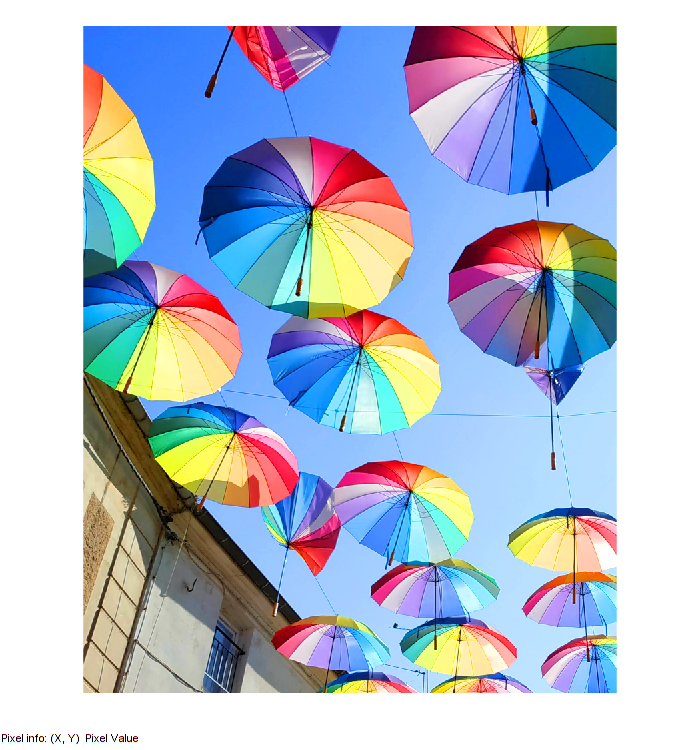

close all; clear variables; 
% In formato RGB non compresso
fileOriginale = 'colors.bmp'; 
x=imread(fileOriginale);
figure;
image(x); axis image; axis off; truesize
impixelinfo

Scorrendo con il mouse la figura generata, si possono visualizzare le coordinate del pixel e le sue componenti RGB. 

## Canali R, G e B

Un'immagine RGB è rappresentata in Matlab tramite una matrice tridimensionale, o se si vuole tramite due matrici bi-dimensionali. 

È facile accedere a tali dati. 

Per prima cosa, verifichiamo la struttura dati dell'immagine a colori appena letta dal file: 

whos x

  Name         Size                 Bytes  Class    Attributes

  x         1000x800x3            2400000  uint8              



Si tratta di un immagine di $1000\times 800$ pixel, ognuno dei quali espresso tramite tre canali. Per accedere ad un canale bisogna usare la terza coordinata:

R = x(:,:,1);
G = x(:,:,2);
B = x(:,:,3);
whos R G B

  Name         Size              Bytes  Class    Attributes

  B         1000x800            800000  uint8              
  G         1000x800            800000  uint8              
  R         1000x800            800000  uint8              



Notiamo che ognuna delle tre matrici R, G e B è una matrice di dimensione $1000\times 800$. Rappresentiamo i contributi di ognua di esse.

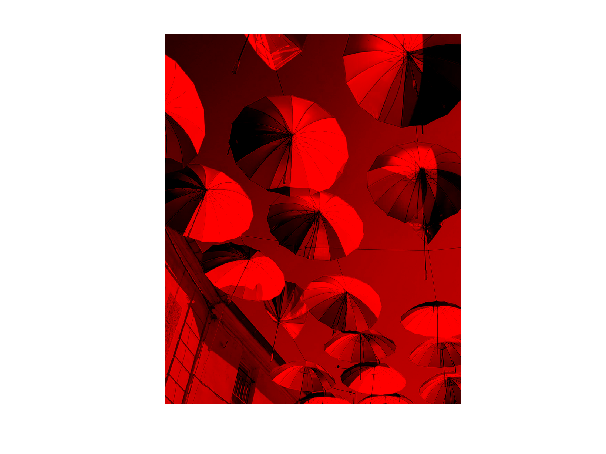

figure;
levels = linspace(0,1,256);
cmapR=[levels',zeros(256,2)]; % Questo codice dice a Matlab che i valori in questa matrice sono in scala di rosso
image(R); 
colormap(cmapR); axis image; axis off

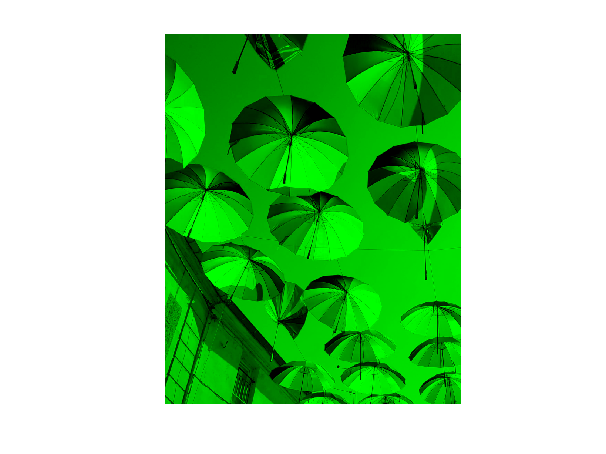



figure;
cmapG=[zeros(256,1), levels',zeros(256,1)];
image(G); 
colormap(cmapG); axis image; axis off

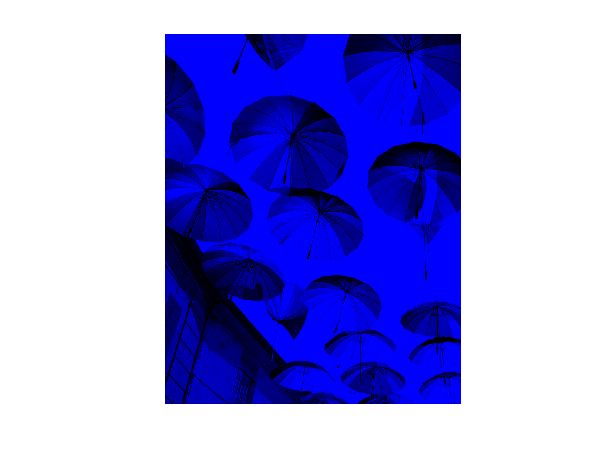



figure;
cmapB=[zeros(256,2),levels'];
image(B); 
colormap(cmapB); axis image; axis off

Come si vede, le tre immagini sono fortemente correlate. Il segnale non è sparso in questa rappresentazione, perche tutte le informazioni hanno (grosso modo) la stessa importanza. Se uno dei tre canali di colore viene degradato, l'effetto si vedrà su tutta l'immagine. 

#### Cambiamento di spazio di colore

Il cambiamento di spazio di colore si realizza molto facilemente in Matlab grazie all'utilizzo di un opportuno Toolbox: `images`

Basterà usare la funzione `rgb2ycbcr` per cambiare lo spazio di colore:

YCbCr= rgb2ycbcr(x);
whos x YCbCr

  Name          Size                 Bytes  Class    Attributes

  YCbCr      1000x800x3            2400000  uint8              
  x          1000x800x3            2400000  uint8              




[N, M, C] = size(x);
Y = YCbCr(:,:,1);
Cb = YCbCr(:,:,2);
Cr = YCbCr(:,:,3);

Mostriamo le tre componenti: 

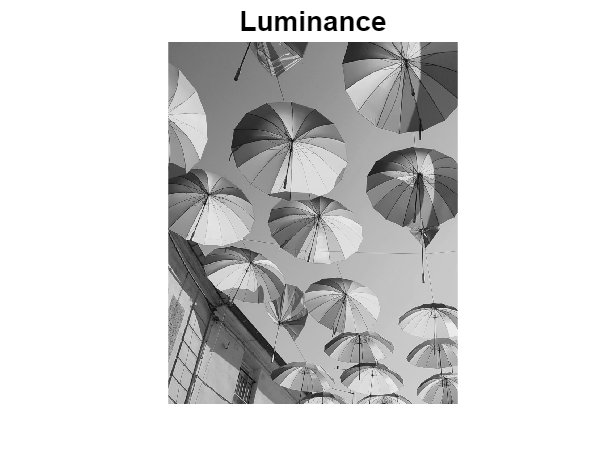

figure;
image(Y); colormap("gray"); title('Luminance')
axis image; axis off;

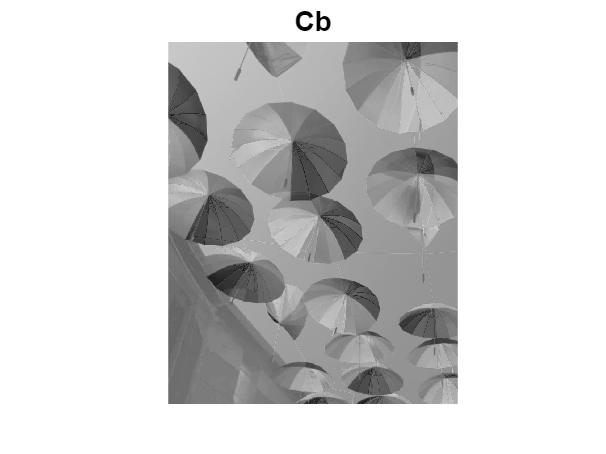


figure;
image(Cb); colormap("gray"); title('Cb')
axis image; axis off;

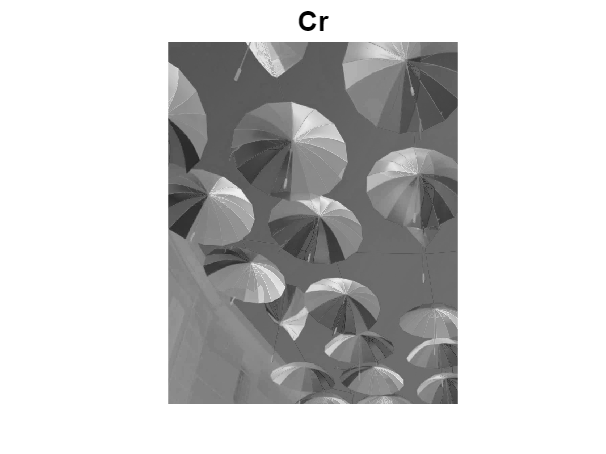


figure;
image(Cr); colormap("gray");  title('Cr')
axis image; axis off;

#### Sottocampionamento del colore.

Adesso effettuiamo un sottocampionamento (sarebbe più corretto usare il termine *decimazione*, perché i dati d'ingresso sono già in forma numerica) delle componenti di crominanza. Prendiamo solo i campioni su righe e colonne dispari. Stiamo quindi conservando un quarto dei campioni di crominanza e semplicemente scartando 3 campioni su 4

Cb2 = Cb(1:2:end,1:2:end);
Cr2 = Cr(1:2:end,1:2:end);
whos R G B Y Cb Cr Cb2 Cr2

  Name         Size              Bytes  Class    Attributes

  B         1000x800            800000  uint8              
  Cb        1000x800            800000  uint8              
  Cb2        500x400            200000  uint8              
  Cr        1000x800            800000  uint8              
  Cr2        500x400            200000  uint8              
  G         1000x800            800000  uint8              
  R         1000x800            800000  uint8              
  Y         1000x800            800000  uint8              



L'immagine formata dalle componenti `Y,` `Cb2, Cr2 `è spesso indicata come immagine in formato **YUV-420. **Il termine YUV si riferisce al cambiamento di spazio di colore (è in pratica visto come sinonimo di YCbCr); invece il termine 420 (o 4:2:0) si riferisce al particolare sottocampionamento spaziale dell'immagine.

#### Scrittura su file

Scriviamo ora l'immagine in formato YUV420 su di un file. Le funzioni da usare hanno sintassi e semantica simile alle funzioni in linguaggio C. 

fileName = 'test.ycbcr';
fid = fopen(fileName,'w');
fwrite(fid, Y(:),  "uint8"); % Scrive tutti i valori di luminanza come interi senza segno su 8 bit
fwrite(fid, Cb2(:),  "uint8"); % Similmente per Cb sottocampionata
fwrite(fid, Cr2(:),  "uint8"); % e per Cr
fclose(fid);

Verifichiamo le dimensioni dei file prima e dopo il sottocampionamento della crominanza:

fprintf('Il file %s ha dimensione %d bytes\n', fileOriginale,   dir(fileOriginale).bytes); 

Il file colors.bmp ha dimensione 2400054 bytes


fprintf('Il file %s ha dimensione %d bytes\n', fileName,   dir(fileName).bytes); 

Il file test.ycbcr ha dimensione 1200000 bytes


NB. Il file RGB ha 54 byte di header. Il file ycbcr non ha header. 

#### Ritorno allo spazio di colore RGB

Effettuiamo interpolazione di ordine zero e conversione dello spazio di colore ed analizziamo i risultati. L'interpolazione di ordine zero si può ottenere in modo efficiente utilizzando il cosiddetto prodotto di Kronecker. 

CB_Interp = uint8(kron(double(Cb2), ones(2)));
CR_Interp = uint8(kron(double(Cr2), ones(2)));

YCbCrInterp=zeros(size(YCbCr));
YCbCrInterp(:,:,1) = Y;
YCbCrInterp(:,:,2) = CB_Interp;
YCbCrInterp(:,:,3) = CR_Interp;

RGB2 = ycbcr2rgb(uint8(YCbCrInterp));

Mostriamo ora l'immagine ricostruita insieme all'originale

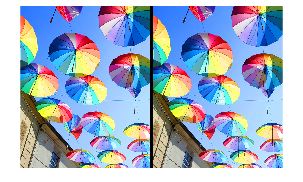

figure;
image([x, zeros(size(x,1),20,3), RGB2]);
axis image; truesize; axis off;

Mostriamo l'immagine di errore e calcoliamo l'MSE

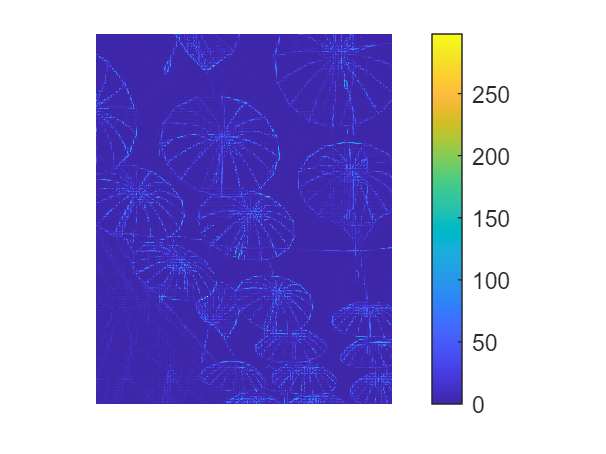

error = double(x)-double(RGB2);
figure;
% Sommiamo i moduli degli errori dei tre canali per ottenere un singolo valore d'errore per pixel 
imagesc(sum(abs(error),3)); 
axis image; axis off; colorbar;


fprintf('L''errore quadratico medio è: %5.4f\n', mean(error(:).^2));

L'errore quadratico medio è: 40.9427


## Conclusione

Il sottocampionamento della crominanza (cioè il passaggio dal formato RGB al formato YUV420) permette di dimezzare le dimensioni dell'immagine. L'immagine viene modificata ($\textrm{MSE}\not= 0$) ma questo non ha impatto sulla qualità percepita, anche nel caso in cui per ricostruire le componenti di crominanza si usi una semplicissima interpolazione di ordine 0 (replicazione del valore). 

Per questi motivi, il formato YUV 420 è di gran lunga il più comune per la rappresentazione compatta di immagini e soprattutto video a colori.